clear;
clc;
close all;
%%%%% 根据得到的各关节角度值，使用3xigma原则（混合高斯分布）求解优化范围 %%%%%

load('Vari_Joi1.mat');
load('Vari_Joi2.mat');
load('Vari_Joi3.mat');
load('Vari_Joi4.mat');
load('Vari_Joi5.mat');
load('Vari_Joi6.mat');
load('Vari_Joi7.mat');
samples_1 = Vari_Joi1;
samples_2 = Vari_Joi2;
samples_3 = Vari_Joi3;
samples_4 = Vari_Joi4;
samples_5 = Vari_Joi5;
samples_6 = Vari_Joi6;
samples_7 = Vari_Joi7;

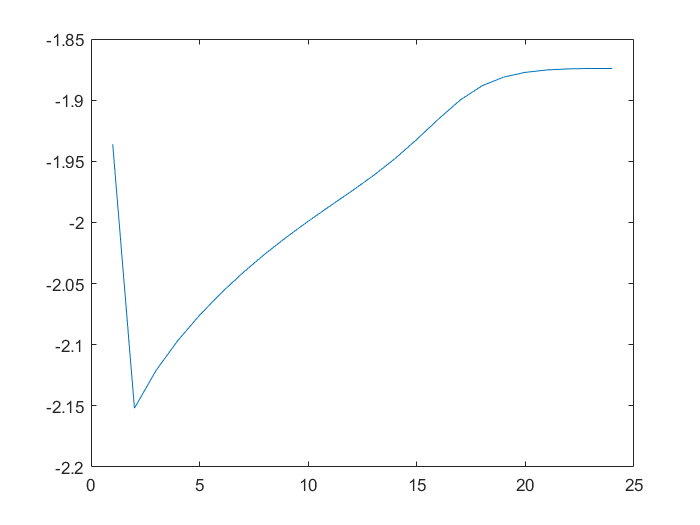

%%%% 关节2的优化范围求解

DD_2 = size(samples_2,2);
NN_2 = size(samples_2,1);

KK_2 = 4;    %用K个正态分布拟合，后续需根据自己的数据修改
Pi_2=ones(1,KK_2)/KK_2;        % 权重系数
Miu_2=cell(KK_2,1);          % 平均值
Sigma2_2=cell(KK_2,1);
Sigma_2=cell(KK_2,1);    % 求解标准差

%% %K均值聚类确定初值
[idx_2,center_2]=kmeans(samples_2,KK_2);
for ii = 1:KK_2
    miu0=center_2(ii,:);
    sigma0=var(samples_2(find(idx_2==ii),:));
    Miu_2{ii,1}=miu0;
    Sigma2_2{ii,1}=sigma0;
end

beta_2=inf;
likelihood_function_value_2=0;
record_2 = [];
%% %EM算法
while(1)
    %% %E步
    gama_2 =zeros(NN_2,KK_2);
    samples_pd_2=zeros(NN_2,KK_2);
    for jj = 1:KK_2
        samples_pd_2(:,jj)=normpdf(samples_2,Miu_2{jj,1},sqrt(Sigma2_2{jj,1}));
    end
    for ii=1:NN_2
        for jj=1:KK_2
            gama_2(ii,jj)=Pi_2(jj)*samples_pd_2(ii,jj)/(Pi_2*samples_pd_2(ii,:)');
        end
    end

    likelihood_function_value_old_2 =likelihood_function_value_2;
    likelihood_function_value_2=sum(log(sum(samples_pd_2.*repmat(Pi_2,NN_2,1),1)));
    record_2=[record_2,likelihood_function_value_2];
    beta_2=abs(likelihood_function_value_2-likelihood_function_value_old_2);
    if beta_2<0.0001
        plot(1:length(record_2),record_2)
        break
    end
    %% %M步
    Nk_2=sum(gama_2,1);
    for jj=1:KK_2
        Miu_2{jj,1}=zeros(1,DD_2);
        Sigma2_2{jj,1}=zeros(DD_2,DD_2);
        for ii=1:NN_2
            Miu_2{jj,1}=Miu_2{jj,1}+gama_2(ii,jj)*samples_2(ii,:)/Nk_2(jj);
        end
        for ii=1:NN_2
            Sigma2_2{jj,1}=Sigma2_2{jj,1}+(gama_2(ii,jj)*(samples_2(ii,:)-Miu_2{jj,1})'*(samples_2(ii,:)-Miu_2{jj,1}))/Nk_2(jj);
        end
    end
    Pi_2=Nk_2/NN_2;
end


X_2 = [min(samples_2(:,1)):0.01:max(samples_2(:,1))]';
YX1_2=zeros(size(X_2,1),KK_2);
for jj=1:KK_2
    YX1_2(:,jj)=normpdf(X_2,Miu_2{jj,1},sqrt(Sigma2_2{jj,1}));
end
for jj=1:KK_2
    Sigma_2{jj,1} = sqrt(Sigma2_2{jj,1});
end
for jj=1:KK_2       %%%% 该循环用于求解满足3xigma原则的关节范围
    sigma2_1fu(jj) = Miu_2{jj,1} - Sigma_2{jj,1};
    sigma2_1zheng(jj) = Miu_2{jj,1} + Sigma_2{jj,1};
    sigma2_2fu(jj) = Miu_2{jj,1} - 2 * Sigma_2{jj,1};
    sigma2_2zheng(jj) = Miu_2{jj,1} + 2 * Sigma_2{jj,1};
    sigma2_3fu(jj) = Miu_2{jj,1} -3 * Sigma_2{jj,1};
    sigma2_3zheng(jj) = Miu_2{jj,1} + 3 * Sigma_2{jj,1};
end


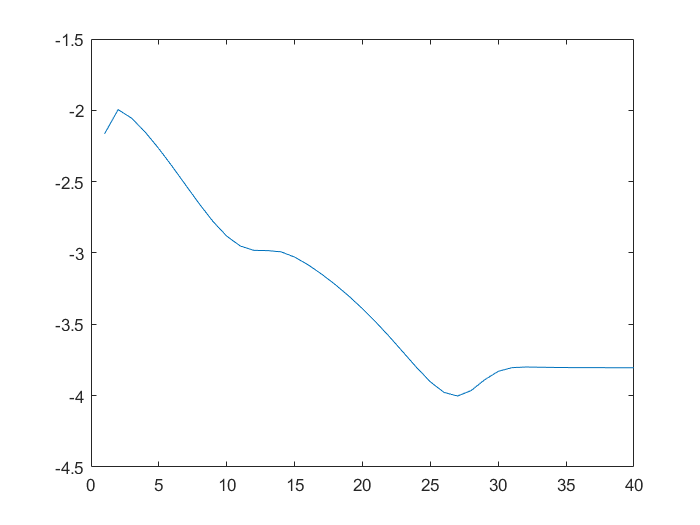

%%%% 关节3的优化范围求解

DD_3 = size(samples_3,2);
NN_3 = size(samples_3,1);

KK_3 = 3;    %用K个正态分布拟合，后续需根据自己的数据修改
Pi_3=ones(1,KK_3)/KK_3;        % 权重系数
Miu_3=cell(KK_3,1);          % 平均值
Sigma2_3=cell(KK_3,1);
Sigma_3=cell(KK_3,1);    % 求解标准差

%% %K均值聚类确定初值
[idx_3,center_3]=kmeans(samples_3,KK_3);
for ii = 1:KK_3
    miu0=center_3(ii,:);
    sigma0=var(samples_3(find(idx_3==ii),:));
    Miu_3{ii,1}=miu0;
    Sigma2_3{ii,1}=sigma0;
end

beta_3 = inf;
likelihood_function_value_3 =0;
record_3 = [];
%% %EM算法
while(1)
    %% %E步
    gama_3 =zeros(NN_3,KK_3);
    samples_pd_3 =zeros(NN_3,KK_3);
    for jj = 1:KK_3
        samples_pd_3(:,jj)=normpdf(samples_3,Miu_3{jj,1},sqrt(Sigma2_3{jj,1}));
    end
    for ii=1:NN_3
        for jj=1:KK_3
            gama_3(ii,jj)=Pi_3(jj)*samples_pd_3(ii,jj)/(Pi_3*samples_pd_3(ii,:)');
        end
    end

    likelihood_function_value_old_3 =likelihood_function_value_3;
    likelihood_function_value_3 = sum(log(sum(samples_pd_3.*repmat(Pi_3,NN_3,1),1)));
    record_3=[record_3,likelihood_function_value_3];
    beta_3=abs(likelihood_function_value_3-likelihood_function_value_old_3);
    if beta_3<0.0001
        plot(1:length(record_3),record_3)
        break
    end
    %% %M步
    Nk_3 =sum(gama_3,1);
    for jj=1:KK_3
        Miu_3{jj,1}=zeros(1,DD_3);
        Sigma2_3{jj,1}=zeros(DD_3,DD_3);
        for ii=1:NN_3
            Miu_3{jj,1}=Miu_3{jj,1}+gama_3(ii,jj)*samples_3(ii,:)/Nk_3(jj);
        end
        for ii=1:NN_3
            Sigma2_3{jj,1}=Sigma2_3{jj,1}+(gama_3(ii,jj)*(samples_3(ii,:)-Miu_3{jj,1})'*(samples_3(ii,:)-Miu_3{jj,1}))/Nk_3(jj);
        end
    end
    Pi_3=Nk_3/NN_3;
end


X_3 = [min(samples_3(:,1)):0.01:max(samples_3(:,1))]';
YX1_3=zeros(size(X_3,1),KK_3);
for jj=1:KK_3
    YX1_3(:,jj)=normpdf(X_3,Miu_3{jj,1},sqrt(Sigma2_3{jj,1}));
end
for jj=1:KK_3
    Sigma_3{jj,1} = sqrt(Sigma2_3{jj,1});
end
for jj=1:KK_3       %%%% 该循环用于求解满足3xigma原则的关节范围
    sigma3_1fu(jj) = Miu_3{jj,1} - Sigma_3{jj,1};
    sigma3_1zheng(jj) = Miu_3{jj,1} + Sigma_3{jj,1};
    sigma3_2fu(jj) = Miu_3{jj,1} - 2 * Sigma_3{jj,1};
    sigma3_2zheng(jj) = Miu_3{jj,1} + 2 * Sigma_3{jj,1};
    sigma3_3fu(jj) = Miu_3{jj,1} -3 * Sigma_3{jj,1};
    sigma3_3zheng(jj) = Miu_3{jj,1} + 3 * Sigma_3{jj,1};
end



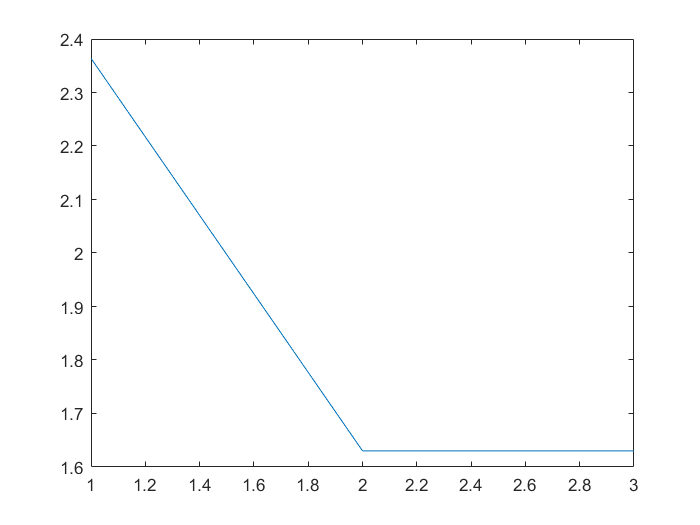

%%%% 关节4的优化范围求解

DD_4 = size(samples_4,2);
NN_4 = size(samples_4,1);

KK_4 = 4;    %用K个正态分布拟合，后续需根据自己的数据修改
Pi_4 =ones(1,KK_4)/KK_4;        % 权重系数
Miu_4 =cell(KK_4,1);          % 平均值
Sigma2_4 =cell(KK_4,1);
Sigma_4 =cell(KK_4,1);    % 求解标准差

%% %K均值聚类确定初值
[idx_4,center_4]=kmeans(samples_4,KK_4);
for ii = 1:KK_4
    miu0=center_4(ii,:);
    sigma0=var(samples_4(find(idx_4==ii),:));
    Miu_4{ii,1}=miu0;
    Sigma2_4{ii,1}=sigma0;
end

beta_4 = inf;
likelihood_function_value_4 =0;
record_4 = [];
%% %EM算法
while(1)
    %% %E步
    gama_4 =zeros(NN_4,KK_4);
    samples_pd_4 =zeros(NN_4,KK_4);
    for jj = 1:KK_4
        samples_pd_4(:,jj)=normpdf(samples_4,Miu_4{jj,1},sqrt(Sigma2_4{jj,1}));
    end
    for ii=1:NN_4
        for jj=1:KK_4
            gama_4(ii,jj)=Pi_4(jj)*samples_pd_4(ii,jj)/(Pi_4*samples_pd_4(ii,:)');
        end
    end

    likelihood_function_value_old_4 =likelihood_function_value_4;
    likelihood_function_value_4 = sum(log(sum(samples_pd_4.*repmat(Pi_4,NN_4,1),1)));
    record_4=[record_4,likelihood_function_value_4];
    beta_4=abs(likelihood_function_value_4-likelihood_function_value_old_4);
    if beta_4<0.0001
        plot(1:length(record_4),record_4)
        break
    end
    %% %M步
    Nk_4 =sum(gama_4,1);
    for jj=1:KK_4
        Miu_4{jj,1}=zeros(1,DD_4);
        Sigma2_4{jj,1}=zeros(DD_4,DD_4);
        for ii=1:NN_4
            Miu_4{jj,1}=Miu_4{jj,1}+gama_4(ii,jj)*samples_4(ii,:)/Nk_4(jj);
        end
        for ii=1:NN_4
            Sigma2_4{jj,1}=Sigma2_4{jj,1}+(gama_4(ii,jj)*(samples_4(ii,:)-Miu_4{jj,1})'*(samples_4(ii,:)-Miu_4{jj,1}))/Nk_4(jj);
        end
    end
    Pi_4=Nk_4/NN_4;
end


X_4 = [min(samples_4(:,1)):0.01:max(samples_4(:,1))]';
YX1_4 =zeros(size(X_4,1),KK_4);
for jj=1:KK_4
    YX1_4(:,jj)=normpdf(X_4,Miu_4{jj,1},sqrt(Sigma2_4{jj,1}));
end
for jj=1:KK_4
    Sigma_4{jj,1} = sqrt(Sigma2_4{jj,1});
end
for jj=1:KK_4       %%%% 该循环用于求解满足3xigma原则的关节范围
    sigma4_1fu(jj) = Miu_4{jj,1} - Sigma_4{jj,1};
    sigma4_1zheng(jj) = Miu_4{jj,1} + Sigma_4{jj,1};
    sigma4_2fu(jj) = Miu_4{jj,1} - 2 * Sigma_4{jj,1};
    sigma4_2zheng(jj) = Miu_4{jj,1} + 2 * Sigma_4{jj,1};
    sigma4_3fu(jj) = Miu_4{jj,1} -3 * Sigma_4{jj,1};
    sigma4_3zheng(jj) = Miu_4{jj,1} + 3 * Sigma_4{jj,1};
end



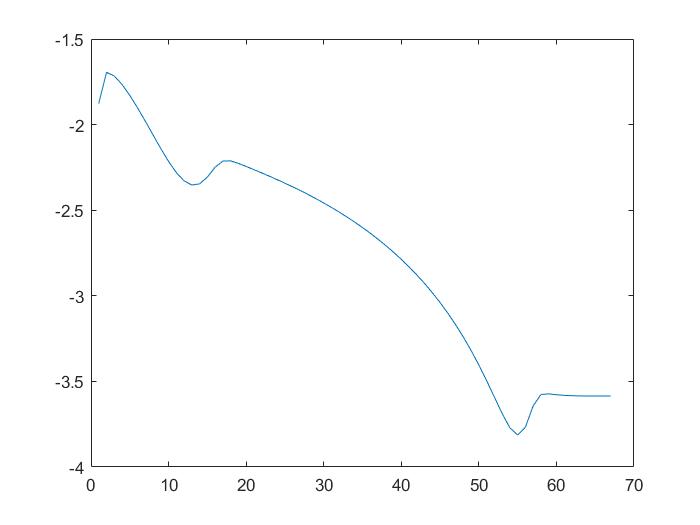

%%%% 关节5的优化范围求解

DD_5 = size(samples_5,2);
NN_5 = size(samples_5,1);

KK_5 = 3;    %用K个正态分布拟合，后续需根据自己的数据修改
Pi_5 =ones(1,KK_5)/KK_5;        % 权重系数
Miu_5 =cell(KK_5,1);          % 平均值
Sigma2_5 =cell(KK_5,1);
Sigma_5 =cell(KK_5,1);    % 求解标准差

%% %K均值聚类确定初值
[idx_5,center_5]=kmeans(samples_5,KK_5);
for ii = 1:KK_5
    miu0=center_5(ii,:);
    sigma0=var(samples_5(find(idx_5==ii),:));
    Miu_5{ii,1}=miu0;
    Sigma2_5{ii,1}=sigma0;
end

beta_5 = inf;
likelihood_function_value_5 =0;
record_5 = [];
%% %EM算法
while(1)
    %% %E步
    gama_5 =zeros(NN_5,KK_5);
    samples_pd_5 =zeros(NN_5,KK_5);
    for jj = 1:KK_5
        samples_pd_5(:,jj)=normpdf(samples_5,Miu_5{jj,1},sqrt(Sigma2_5{jj,1}));
    end
    for ii=1:NN_5
        for jj=1:KK_5
            gama_5(ii,jj)=Pi_5(jj)*samples_pd_5(ii,jj)/(Pi_5*samples_pd_5(ii,:)');
        end
    end

    likelihood_function_value_old_5 =likelihood_function_value_5;
    likelihood_function_value_5 = sum(log(sum(samples_pd_5.*repmat(Pi_5,NN_5,1),1)));
    record_5=[record_5,likelihood_function_value_5];
    beta_5 =abs(likelihood_function_value_5-likelihood_function_value_old_5);
    if beta_5<0.0001
        plot(1:length(record_5),record_5)
        break
    end
    %% %M步
    Nk_5 =sum(gama_5,1);
    for jj=1:KK_5
        Miu_5{jj,1}=zeros(1,DD_5);
        Sigma2_5{jj,1}=zeros(DD_5,DD_5);
        for ii=1:NN_5
            Miu_5{jj,1}=Miu_5{jj,1}+gama_5(ii,jj)*samples_5(ii,:)/Nk_5(jj);
        end
        for ii=1:NN_5
            Sigma2_5{jj,1}=Sigma2_5{jj,1}+(gama_5(ii,jj)*(samples_5(ii,:)-Miu_5{jj,1})'*(samples_5(ii,:)-Miu_5{jj,1}))/Nk_5(jj);
        end
    end
    Pi_5=Nk_5/NN_5;
end


X_5 = [min(samples_5(:,1)):0.01:max(samples_5(:,1))]';
YX1_5 =zeros(size(X_5,1),KK_5);
for jj=1:KK_5
    YX1_5(:,jj)=normpdf(X_5,Miu_5{jj,1},sqrt(Sigma2_5{jj,1}));
end
for jj=1:KK_5
    Sigma_5{jj,1} = sqrt(Sigma2_5{jj,1});
end
for jj=1:KK_5       %%%% 该循环用于求解满足3xigma原则的关节范围
    sigma5_1fu(jj) = Miu_5{jj,1} - Sigma_5{jj,1};
    sigma5_1zheng(jj) = Miu_5{jj,1} + Sigma_5{jj,1};
    sigma5_2fu(jj) = Miu_5{jj,1} - 2 * Sigma_5{jj,1};
    sigma5_2zheng(jj) = Miu_5{jj,1} + 2 * Sigma_5{jj,1};
    sigma5_3fu(jj) = Miu_5{jj,1} -3 * Sigma_5{jj,1};
    sigma5_3zheng(jj) = Miu_5{jj,1} + 3 * Sigma_5{jj,1};
end



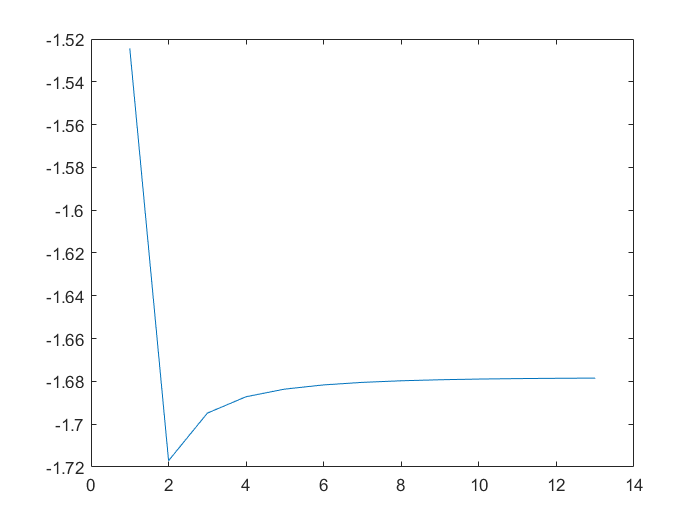

%%% 关节6的优化范围求解

% samples = [normrnd(5,1,[1000,1]);normrnd(-5,1,[1000,1])];   %这里的sigma是标准差standard deviation
%%% 替换这里的原始数据

DD_6 = size(samples_6,2);
NN_6 = size(samples_6,1);

KK_6 = 4;    %用K个正态分布拟合，后续需根据自己的数据修改
Pi_6=ones(1,KK_6)/KK_6;        % 权重系数
Miu_6=cell(KK_6,1);          % 平均值
Sigma2_6=cell(KK_6,1);
Sigma_6=cell(KK_6,1);    % 求解标准差

%% %K均值聚类确定初值
[idx_6,center_6]=kmeans(samples_6,KK_6);
for ii = 1:KK_6
    miu0=center_6(ii,:);
    sigma0=var(samples_6(find(idx_6==ii),:));
    Miu_6{ii,1}=miu0;
    Sigma2_6{ii,1}=sigma0;
end

beta_6=inf;
likelihood_function_value_6=0;
record_6=[];
%% %EM算法
while(1)
    %% %E步
    gama_6=zeros(NN_6,KK_6);
    samples_pd_6=zeros(NN_6,KK_6);
    for jj = 1:KK_6
        samples_pd_6(:,jj)=normpdf(samples_6,Miu_6{jj,1},sqrt(Sigma2_6{jj,1}));
    end
    for ii=1:NN_6
        for jj=1:KK_6
            gama_6(ii,jj)=Pi_6(jj)*samples_pd_6(ii,jj)/(Pi_6*samples_pd_6(ii,:)');
        end
    end

    likelihood_function_value_old_6=likelihood_function_value_6;
    likelihood_function_value_6=sum(log(sum(samples_pd_6.*repmat(Pi_6,NN_6,1),1)));
    record_6=[record_6,likelihood_function_value_6];
    beta_6=abs(likelihood_function_value_6-likelihood_function_value_old_6);
    if beta_6<0.0001
        plot(1:length(record_6),record_6)
        break
    end
    %% %M步
    Nk_6=sum(gama_6,1);
    for jj=1:KK_6
        Miu_6{jj,1}=zeros(1,DD_6);
        Sigma2_6{jj,1}=zeros(DD_6,DD_6);
        for ii=1:NN_6
            Miu_6{jj,1}=Miu_6{jj,1}+gama_6(ii,jj)*samples_6(ii,:)/Nk_6(jj);
        end
        for ii=1:NN_6
            Sigma2_6{jj,1}=Sigma2_6{jj,1}+(gama_6(ii,jj)*(samples_6(ii,:)-Miu_6{jj,1})'*(samples_6(ii,:)-Miu_6{jj,1}))/Nk_6(jj);
        end
    end
    Pi_6=Nk_6/NN_6;
end


X_6 = [min(samples_6(:,1)):0.01:max(samples_6(:,1))]';
YX1_6=zeros(size(X_6,1),KK_6);
for jj=1:KK_6
    YX1_6(:,jj)=normpdf(X_6,Miu_6{jj,1},sqrt(Sigma2_6{jj,1}));
end
for jj=1:KK_6
    Sigma_6{jj,1} = sqrt(Sigma2_6{jj,1});
end
for jj=1:KK_6       %%%% 该循环用于求解满足3xigma原则的关节范围
    sigma6_1fu(jj) = Miu_6{jj,1} - Sigma_6{jj,1};
    sigma6_1zheng(jj) = Miu_6{jj,1} + Sigma_6{jj,1};
    sigma6_2fu(jj) = Miu_6{jj,1} - 2 * Sigma_6{jj,1};
    sigma6_2zheng(jj) = Miu_6{jj,1} + 2 * Sigma_6{jj,1};
    sigma6_3fu(jj) = Miu_6{jj,1} -3 * Sigma_6{jj,1};
    sigma6_3zheng(jj) = Miu_6{jj,1} + 3 * Sigma_6{jj,1};
end

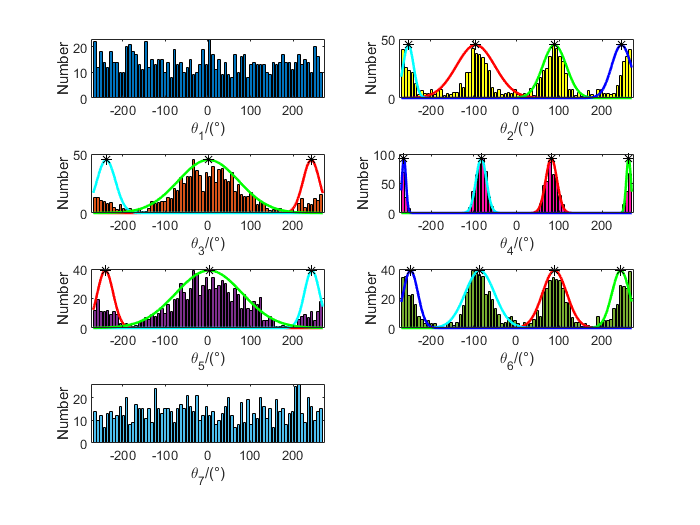

%%%%  绘制各关节的优化范围分布图
figure;
subplot(4,2,1);
[count_1,centers_1]=hist(samples_1,72);
Fig_Joi1 = bar(centers_1,count_1);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi1.FaceColor = [0.00,0.45,0.74];
xlabel ('\theta_1/(°)');
ylabel ('Number');

subplot(4,2,2);
[count_2,centers_2]=hist(samples_2,72);
Fig_Joi2 = bar(centers_2,count_2);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi2.FaceColor = [1.00 1.00 0.07];
xlabel ('\theta_2/(°)');
ylabel ('Number');
hold on;
plot(X_2, YX1_2(:,1)/max(YX1_2(:,1))*max(count_2),'r','linewidth',1.5);
plot(X_2, YX1_2(:,2)/max(YX1_2(:,2))*max(count_2),'c','linewidth',1.5);
plot(X_2, YX1_2(:,3)/max(YX1_2(:,3))*max(count_2),'g','linewidth',1.5);
plot(X_2, YX1_2(:,4)/max(YX1_2(:,4))*max(count_2),'b','linewidth',1.5);
plot(Miu_2{1,1}, max(YX1_2(:,1)/max(YX1_2(:,1))*max(count_2)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_2{2,1}, max(YX1_2(:,1)/max(YX1_2(:,1))*max(count_2)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_2{3,1}, max(YX1_2(:,1)/max(YX1_2(:,1))*max(count_2)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_2{4,1}, max(YX1_2(:,1)/max(YX1_2(:,1))*max(count_2)),'Marker','*','MarkerEdgeColor','k');
YX2_2 = sum(YX1_2.*repmat(Pi_2,size(X_2,1),1),2);
YX2_2=YX2_2/max(YX2_2)*max(count_2);

subplot(4,2,3);
[count_3,centers_3]=hist(samples_3,72);
Fig_Joi3 = bar(centers_3,count_3);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi3.FaceColor = [0.8500 0.3250 0.0980];
xlabel ('\theta_3/(°)');
ylabel ('Number');
hold on;
plot(X_3, YX1_3(:,1)/max(YX1_3(:,1))*max(count_3),'r','linewidth',1.5);
plot(X_3, YX1_3(:,2)/max(YX1_3(:,2))*max(count_3),'c','linewidth',1.5);
plot(X_3, YX1_3(:,3)/max(YX1_3(:,3))*max(count_3),'g','linewidth',1.5);
plot(Miu_3{1,1}, max(YX1_3(:,1)/max(YX1_3(:,1))*max(count_3)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_3{2,1}, max(YX1_3(:,1)/max(YX1_3(:,1))*max(count_3)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_3{3,1}, max(YX1_3(:,1)/max(YX1_3(:,1))*max(count_3)),'Marker','*','MarkerEdgeColor','k');
YX2_3 = sum(YX1_3.*repmat(Pi_3,size(X_3,1),1),2);
YX2_3=YX2_3/max(YX2_3)*max(count_3);

subplot(4,2,4);
[count_4,centers_4] =hist(samples_4,72);
Fig_Joi4 = bar(centers_4,count_4);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi4.FaceColor = [1.00,0.07,0.65];
xlabel ('\theta_4/(°)');
ylabel ('Number');
hold on;
plot(X_4, YX1_4(:,1)/max(YX1_4(:,1))*max(count_4),'r','linewidth',1.5);
plot(X_4, YX1_4(:,2)/max(YX1_4(:,2))*max(count_4),'c','linewidth',1.5);
plot(X_4, YX1_4(:,3)/max(YX1_4(:,3))*max(count_4),'g','linewidth',1.5);
plot(X_4, YX1_4(:,4)/max(YX1_4(:,4))*max(count_4),'b','linewidth',1.5);
plot(Miu_4{1,1}, max(YX1_4(:,1)/max(YX1_4(:,1))*max(count_4)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_4{2,1}, max(YX1_4(:,1)/max(YX1_4(:,1))*max(count_4)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_4{3,1}, max(YX1_4(:,1)/max(YX1_4(:,1))*max(count_4)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_4{4,1}, max(YX1_4(:,1)/max(YX1_4(:,1))*max(count_4)),'Marker','*','MarkerEdgeColor','k');
YX2_4 = sum(YX1_4.*repmat(Pi_4,size(X_4,1),1),2);
YX2_4=YX2_4/max(YX2_4)*max(count_4);

subplot(4,2,5);
[count_5,centers_5] =hist(samples_5,72);
Fig_Joi5 = bar(centers_5,count_5);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi5.FaceColor = [0.4940 0.1840 0.5560];
xlabel ('\theta_5/(°)');
ylabel ('Number');
hold on;
plot(X_5, YX1_5(:,1)/max(YX1_5(:,1))*max(count_5),'r','linewidth',1.5);
plot(X_5, YX1_5(:,2)/max(YX1_5(:,2))*max(count_5),'c','linewidth',1.5);
plot(X_5, YX1_5(:,3)/max(YX1_5(:,3))*max(count_5),'g','linewidth',1.5);
plot(Miu_5{1,1}, max(YX1_5(:,1)/max(YX1_5(:,1))*max(count_5)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_5{2,1}, max(YX1_5(:,1)/max(YX1_5(:,1))*max(count_5)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_5{3,1}, max(YX1_5(:,1)/max(YX1_5(:,1))*max(count_5)),'Marker','*','MarkerEdgeColor','k');
YX2_5 = sum(YX1_5.*repmat(Pi_5,size(X_5,1),1),2);
YX2_5=YX2_5/max(YX2_5)*max(count_5);

subplot(4,2,6);
[count_6,centers_6]=hist(samples_6,72);
Fig_Joi6 = bar(centers_6,count_6,'FaceColor',[0.72,0.89,0.98]);
Fig_Joi6.FaceColor = [0.4660 0.6740 0.1880];
xlabel ('\theta_6/(°)');
ylabel ('Number');
hold on;
plot(X_6, YX1_6(:,1)/max(YX1_6(:,1))*max(count_6),'r','linewidth',1.5);
plot(X_6, YX1_6(:,2)/max(YX1_6(:,2))*max(count_6),'c','linewidth',1.5);
plot(X_6, YX1_6(:,3)/max(YX1_6(:,3))*max(count_6),'g','linewidth',1.5);
plot(X_6, YX1_6(:,4)/max(YX1_6(:,4))*max(count_6),'b','linewidth',1.5);
plot(Miu_6{1,1}, max(YX1_6(:,1)/max(YX1_6(:,1))*max(count_6)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_6{2,1}, max(YX1_6(:,1)/max(YX1_6(:,1))*max(count_6)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_6{3,1}, max(YX1_6(:,1)/max(YX1_6(:,1))*max(count_6)),'Marker','*','MarkerEdgeColor','k');
plot(Miu_6{4,1}, max(YX1_6(:,1)/max(YX1_6(:,1))*max(count_6)),'Marker','*','MarkerEdgeColor','k');
YX2_6 = sum(YX1_6.*repmat(Pi_6,size(X_6,1),1),2);
YX2_6=YX2_6/max(YX2_6)*max(count_6);
% plot(X_6,YX2_6,'color',[0.00,0.45,0.74],'linewidth',2);

subplot(4,2,7);
[count_7,centers_7]=hist(samples_7,72);
Fig_Joi7 = bar(centers_7,count_7);      %% ,'FaceColor',[0.72,0.89,0.98]
Fig_Joi7.FaceColor = [0.3010 0.7450 0.9330];
xlabel ('\theta_7/(°)');
ylabel ('Number');